20180202

EE608

close all;
clear;
clc;

1. minimizer or maximizer

use Hessian matrix (the second order sufficient condition for optimization)

%{
syms f(x1,x2)
% f = 2*x1^2-2*x1*x2+x2^2-4*x1-2*x2+4;
% f = x1^2-x2^2;
f = x1^3+x2^3+2*x1^2+4*x2^2+6;
d_f_x1 = diff(f,x1); % first order 
d_f_x2 = diff(f,x2);
[s_x1,s_x2] = solve(d_f_x1 == 0,d_f_x2 == 0); % minimizer or maximizer
s_x1 = double(s_x1); % minimizer or maximizer
s_x2 = double(s_x2); % minimizer or maximizer

H_f = hessian(f) % second order
H(1,:) = double(subs(H_f(1,1),{x1,x2},{s_x1,s_x2}));
H(2,:) = double(subs(det(H_f),{x1,x2},{s_x1,s_x2}));

[row,n] = size(H);
sta = string(zeros(n,1));
for i = 1:n
    sta(i,1) = "saddle"; % the status of the point
    if H(1,i) > 0 && H(2,i) > 0
        sta(i,1) = "minimizer"; % the status of the point
    end
    if H(1,i) < 0 && H(2,i) > 0
        sta(i,1) = "maximizer"; % the status of the point
    end
end

figure,
fsurf(matlabFunction(f),...
    [min(s_x1-2) max(s_x1+2) ...
    min(s_x2-2) max(s_x2+2)]);
% ezsurf('2*x1^2-2*x1*x2+x2^2-4*x1-2*x2+4',[-20 80 -20 80]);
hold on;
plot3(s_x1,s_x2,double(subs(f,{x1,x2},{s_x1,s_x2})),...
    'x','markersize',18);
hold on;
str = strcat(string(s_x1),',',string(s_x2),',',sta);
text(s_x1,s_x2,str,'fontsize',10);
return
%}

2. Lagrange theorem

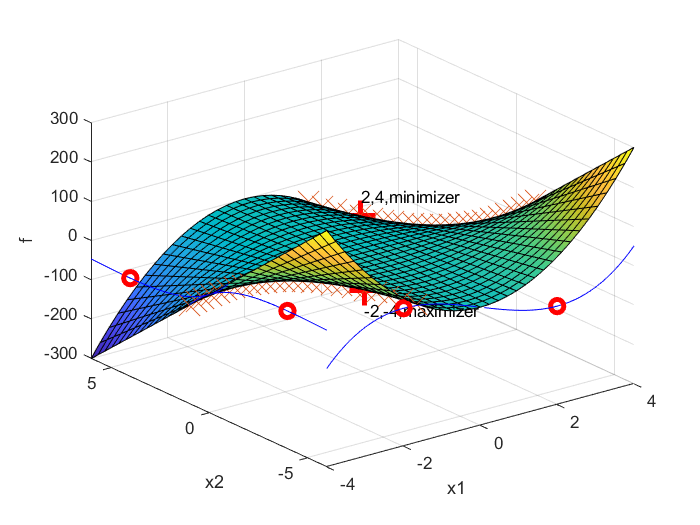

% %{
syms f(x1,x2)
n = 2; % n is the number of variables, the dimension of x

% f = 2*x1+x2+10;
% p_f = 'max'; % point flag
% a(1) = x1+2*x2^2-3; % constrains

syms A0
A0_1 = 24*pi; % the value of A0
f = pi*x1^2*x2;
p_f = 'max'; % point flag
a(1) = 2*pi*x1^2+2*pi*x1*x2-A0; % constrains

[m,p] = size(a); % p is the number of constrains, p<=n
if strcmp(p_f,'max')
    f = -f;
end
lamda = sym ('lamda',size(a));
L = f-lamda.*a;

d_L_x1 = diff(L,x1); % first order 
d_L_x2 = diff(L,x2);
d_L_lamda = diff(L,lamda);
H_L = hessian(L,[x1,x2]);  % second order, hessian matrix
H_a = hessian(a,[x1,x2]);  % hessian matrix, size is n*n
% [x1,x2,lamda] = solve(d_L_x1 == 0,d_L_x2 == 0,d_L_lamda == 0,x1,x2,lamda);

syms z; % determine min or max by the sign of z
d_a = H_a(1:p,:); % the matrix used to concatenate, size is p*n
d_0 = zeros(p);
deter = [H_L-z.*eye(n),d_a.';d_a,d_0]; % reference in the note ...
                                    % EE608 20180201: compute determinal
[z,x1,x2,lamda] = solve(det(deter) == 0,d_L_x1 == 0,...
    d_L_x2 == 0,d_L_lamda == 0,z,x1,x2,lamda);
s_x1 = double(subs(x1,A0,A0_1));
s_x2 = double(subs(x2,A0,A0_1));
s_lamda = double(subs(lamda,A0,A0_1));
s_z = double(subs(z,A0,A0_1));

[p,n] = size(z);
sta = string(zeros(p,1));
for i = 1:p
    sta(i,1) = "saddle"; % the status of the point
    if s_z(i,1) > 0
        sta(i,1) = "minimizer"; % the status of the point
    end
    if s_z(i,1) < 0
        sta(i,1) = "maximizer"; % the status of the point
    end    
end

syms x1 x2
figure,
fsurf(matlabFunction(f),...
    [min(s_x1-2) max(s_x1+2) ...
    min(s_x2-2) max(s_x2+2)]);
hold on;
s_f = double(subs(f,{x1,x2},{s_x1,s_x2}));
plot3(s_x1,s_x2,s_f,'r+','markersize',18,'LineWidth',3); % min or max point on the surf
hold on;
str = strcat(string(s_x1),',',string(s_x2),',',sta);
text(s_x1,s_x2,str,'fontsize',10);
hold on;
t_x1 = min(s_x1-2):0.1:max(s_x1+2);
% t_x2 = 12./t_x1-t_x1; % 
% t_f = -pi*t_x1.^2.*t_x2;
t_x2 = solve(a==0,x2);
t_x2 = subs(t_x2,A0,A0_1);
F_x2 = matlabFunction(t_x2);
t_x2 = F_x2(t_x1);
t_f = double(subs(f,{x1,x2},{t_x1,t_x2}));
t_n1 = min(s_x1-2)*ones(size(t_x1));
t_n2 = min(s_x2-2)*ones(size(t_x1));
plot3(t_x1,t_x2,t_f,'x','markersize',18); % constrains on the surf
hold on;
plot3(t_n1,t_x2,t_f,'b'); % projection on the plain x2-f
plot3(min(s_x1-2)*ones(size(s_f)),s_x2,s_f,'rO','markersize',8,'LineWidth',3);
plot3(t_x1,t_n2,t_f,'b'); % projection on the plain x1-f
plot3(s_x1,min(s_x2-2)*ones(size(s_f)),s_f,'rO','markersize',8,'LineWidth',3);
% plot3(t_x1,t_x2,t_n3); % projection on the plain x1-x2
hold on;

xlim([min(s_x1-2) max(s_x1+2)]),xlabel('x1');
ylim([min(s_x2-2) max(s_x2+2)]),ylabel('x2');
zlabel('f');
% view(0,90);
% view(90,0);view(-90,0)
% view(0,0);
hold off;

return
%}




